# Timed trace demo

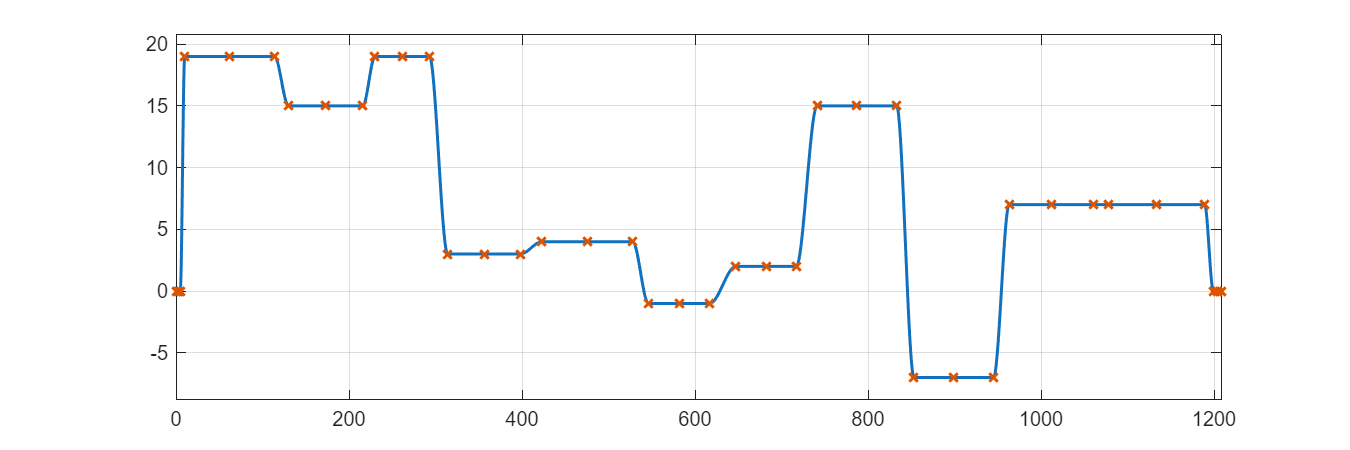

signal_design_matrix = SignalUtil1.generateSignalDesignMatrixFromTraceProperties(...
  RandomSeed = 123, ...
  FInitialValue = 0, ...
  XInitialFlatLength = 5, ...
  XInitialTransitionLength = 5, ...
  NumTransitions = 10, ...
  TransitionXRange = [10 30], ...
  FlatXRange = [60 120], ...
  FRange = [-10 30], ...
  XFinalTransitionLength = 10, ...
  XFinalFlatLength = 10, ...
  FFinalValue = 0 );

data_table = SignalUtil1.getVectorsFromSignalDesignMatrix(signal_design_matrix);

fig = figure;
fig.Position(3:4) = [900 300];  % width height
SignalUtil1.plotLookupTable1D(data_table.X, data_table.F, InterpolationInterval=0.5, ParentAxes=axes(fig))

*Copyright 2025 The MathWorks, Inc.*